clear all
clc
syms x1(t) x2(t) x3(t) y1(t) y2(t) y3(t) xc(t) theta1(t) theta2(t) theta3(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t) N(t)

animate_it = 1;     % set to 1 to plot the animation
save_it = 0;        % set to 1 to save the animation

m = 0.1;            % kg - mass of metronome
M = 0.06;           % kg - mass of cart
IG = 4e-5;          % kgm^2
g = 9.81;           % m/s^2
d = 0.005;          % m
b = 2e-5;           % Ns/rad
escapement_angle = deg2rad(15); % radians

% ---------------------------------------------------------------------------
rG1=[x1(t);y1(t)];      % mass center of metronome 1 
rG2=[x2(t);y2(t)];      % mass center of metronome 2 
rG3=[x3(t);y3(t)];      % mass center of metronome 3 
rGc=[xc(t);0];          % mass center of cart
F1=[F1x(t);F1y(t)];     % reaction force at pin supporting metronome 1
F2=[F2x(t);F2y(t)];     % reaction force at pin supporting metronome 2
F3=[F3x(t);F3y(t)];     % reaction force at pin supporting metronome 3

%F=ma for metronome 1
eq1=m*diff(rG1,t,t)==F1-m*g*[0;1];
MF1G1=cross([rGc;0]-[rG1;0],[F1;0]);
%IG theta''=M for the top arm
eq2=IG*diff(theta1(t),t,t)==MF1G1(3) - b*((theta1(t)/escapement_angle)^2 - 1)*diff(theta1(t),t);

%F=ma for metronome 2
eq3=m*diff(rG2,t,t)==F2-m*g*[0;1];
MF2G2=cross([rGc;0]-[rG2;0],[F2;0]);
%IG theta''=M for the top arm
eq4=IG*diff(theta2(t),t,t)==MF2G2(3) - b*((theta2(t)/escapement_angle)^2 - 1)*diff(theta2(t),t);

%F=ma for metronome 3
eq5=m*diff(rG3,t,t)==F3-m*g*[0;1];
MF3G3=cross([rGc;0]-[rG3;0],[F3;0]);
%IG theta''=M for the top arm
eq6=IG*diff(theta3(t),t,t)==MF3G3(3) - b*((theta3(t)/escapement_angle)^2 - 1)*diff(theta3(t),t);

%F=ma for cart
eq7=M*diff(rGc,t,t)==-F1-F2-F3+[0;N(t)];

%Keep metronome 1 fixed to cart. 
eq8=rG1+d*[-sin(theta1(t));cos(theta1(t))]==rGc;
%Keep metronome 1 fixed to cart. 
eq9=rG2+d*[-sin(theta2(t));cos(theta2(t))]==rGc;
%Keep metronome 1 fixed to cart. 
eq10=rG3+d*[-sin(theta3(t));cos(theta3(t))]==rGc;

DES=[eq1;eq2;eq3;eq4;eq5;eq6;eq7];
disp_const=[eq8;eq9;eq10];
vel_const = [];


The unknown functions (just the base functions, not derivatives) are: F1x(t),F2x(t),F3x(t),F1y(t),F2y(t),F3y(t),N(t),theta1(t),theta2(t),theta3(t),x1(t),x2(t),x3(t),xc(t),y1(t),y2(t),y3(t)
Initial Conditions:
Y0/YP0:
F1x: -0.025657 F1xt:0.000000
F2x: 0.021254 F2xt:0.000000
F3x: 0.002688 F3xt:0.000000
F1y: 0.957075 F1yt:0.000000
F2y: 0.974304 F2yt:0.000000
F3y: 0.981000 F3yt:0.000000
N: 2.912378 Nt:0.000000
theta1: 0.698132 theta1t:0.000000
theta2: -0.349066 theta2t:0.000000
theta3: 0.000000 theta3t:0.000000
x1: 0.003214 x1t:0.000000
x2: -0.001710 x2t:0.000000
x3: 0.000000 x3t:0.000000
xc: 0.000000 xct:0.000000
y1: -0.003830 y1t:0.000000
y2: -0.004698 y2t:0.000000
y3: -0.005000 y3t:0.000000
Dtheta1t: 0.000000 Dtheta1tt:-74.442686
Dtheta2t: 0.000000 Dtheta2tt:39.157360
Dtheta3t: 0.000000 Dtheta3tt:-0.336055
Dx1t: 0.000000 Dx1tt:-0.256567
Dx2t: 0.000000 Dx2tt:0.212544
Dx3t: 0.000000 Dx3tt:0.026884
Dxct: 0.000000 Dxctt:0.028565
Dy1t: 0.000000 Dy1tt:-0.239254
Dy2t: 0.000000 Dy2tt:-0.066963


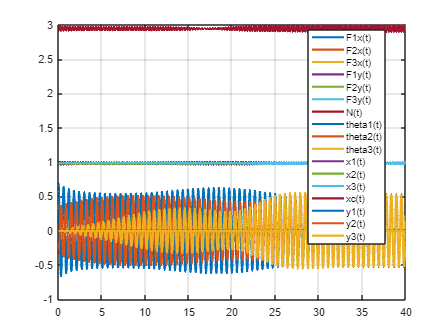


soln=mechanicsAsDAE(DES,disp_const,vel_const,[0 40],{theta1==40*pi/180,theta2==-20*pi/180,theta3==0,diff(theta1)==0,diff(theta2)==0,diff(theta3)==0,xc==0,diff(xc)==0});

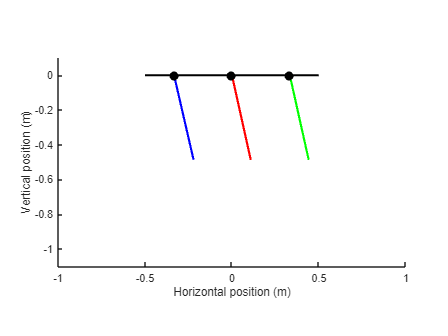

if animate_it == 1
    t_anim = linspace(min(soln.t),max(soln.t),1001)';
    theta1_anim = interp1(soln.t,soln.theta1,t_anim);
    theta2_anim = interp1(soln.t,soln.theta2,t_anim);
    theta3_anim = interp1(soln.t,soln.theta3,t_anim);
    xc_anim = interp1(soln.t,soln.xc,t_anim);
    func_animate_synchronizing_metronomes(t_anim,theta1_anim,theta2_anim,theta3_anim,xc_anim,save_it)
end

% KineticEnergy=1/2*m1*(soln.Dx1t.^2+soln.Dy1t.^2)+1/2*m2*(soln.Dx2t.^2+soln.Dy2t.^2)...
%     +1/2*IG1*soln.Dtheta1t.^2+1/2*IG2*soln.Dtheta2t.^2;
% PotentialEnergy=m1*soln.y1*g+m2*soln.y2*g;
% PotentialEnergy = PotentialEnergy - PotentialEnergy(1);
% SpringEnergy = 1/2*k*(sqrt((w+d*sin(soln.theta2)-d*sin(soln.theta1)).^2 + (-d*cos(soln.theta2)-(-d*cos(soln.theta1))).^2) - w).^2;
% figure
% clf
% hold on
% plot(soln.t,KineticEnergy,'LineWidth',2)
% plot(soln.t,PotentialEnergy,'LineWidth',2)
% plot(soln.t,SpringEnergy,'LineWidth',2)
% plot(soln.t,KineticEnergy+PotentialEnergy+SpringEnergy,'LineWidth',2)
% xlabel('time'); ylabel('Total Energy')
% legend('Kinetic','Potential','Spring','Total')

function [] = func_animate_synchronizing_metronomes(t,theta1,theta2,theta3,xc,save_it)

skip_frame = 1;
L = 1;

if save_it == 1
    %--------------------------------------------------------------------------
    % animate the results
    saveDirName = uigetdir('', ['Specify the directory where the ', ...
        'animations will be saved.']);

    %  Append a slash to the directory name ('/' for Mac, '\' for Windows):
    if isempty(strfind(saveDirName, '/')) == 0
        saveDirName = [saveDirName, '/'];
    else
        saveDirName = [saveDirName, '\'];
    end

    animObj = VideoWriter([saveDirName, 'synchronizing_metronomes.avi']);
    open(animObj)
    skip_frame = 5;
end

%--------------------------------------------------------------------------

for k = 1:length(t)

    R_a_I = [sin(theta1(k)) cos(theta1(k)) 0;-cos(theta1(k)) sin(theta1(k)) 0;0 0 1];
    R_b_I = [sin(theta2(k)) cos(theta2(k)) 0;-cos(theta2(k)) sin(theta2(k)) 0;0 0 1];
    R_c_I = [sin(theta3(k)) cos(theta3(k)) 0;-cos(theta3(k)) sin(theta3(k)) 0;0 0 1];

    temp = [xc(k);0;0] - [2/6*L;0;0];
    r1x_top(k,1) = temp(1);
    r1y_top(k,1) = temp(2);

    temp = R_a_I*[L/2;0;0] + [xc(k);0;0] - [2/6*L;0;0];
    r1x_bot(k,1) = temp(1);
    r1y_bot(k,1) = temp(2);

    temp = [xc(k);0;0];
    r2x_top(k,1) = temp(1);
    r2y_top(k,1) = temp(2);

    temp = R_b_I*[L/2;0;0] + [xc(k);0;0];
    r2x_bot(k,1) = temp(1);
    r2y_bot(k,1) = temp(2);

    temp = [xc(k);0;0] + [2/6*L;0;0];
    r3x_top(k,1) = temp(1);
    r3y_top(k,1) = temp(2);

    temp = R_c_I*[L/2;0;0] + [xc(k);0;0] + [2/6*L;0;0];
    r3x_bot(k,1) = temp(1);
    r3y_bot(k,1) = temp(2);
end

%--------------------------------------------------------------------------

%  Set up the figure window for animation. Hide the window while the
%  animation is being initialized:

figure(101);
clf
xlabel('Horizontal position (m)')
ylabel('Vertical position (m)')
axis equal
axis([-L L -1.1*L 0.1*L])

%--------------------------------------------------------------------------

%  Draw pendulums, joints, and CGs
pend1 = line('xdata', [r1x_top(1) r1x_bot(1)], 'ydata', [r1y_top(1) r1y_bot(1)],...
    'color','b','linewidth',2);
pend2 = line('xdata', [r2x_top(1) r2x_bot(1)], 'ydata', [r2y_top(1) r2y_bot(1)],...
    'color','r','linewidth',2);
pend3 = line('xdata', [r3x_top(1) r3x_bot(1)], 'ydata', [r3y_top(1) r3y_bot(1)],...
    'color','g','linewidth',2);
cart = line('xdata', [xc(1)-L/2 xc(1)+L/2], 'ydata', [0 0],...
    'color','k','linewidth',2);
point1 = line('xdata', r1x_top(1), 'ydata', r1y_top(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 8);
point2 = line('xdata', r2x_top(1), 'ydata', r2y_top(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 8);
point3 = line('xdata', r3x_top(1), 'ydata', r3y_top(1), ...
    'marker', 'o', 'color', 'k', 'markerfacecolor', 'k', 'markersize', 8);


for k = 1:skip_frame:length(t)
    set(pend1, 'xdata', [r1x_top(k) r1x_bot(k)], 'ydata', [r1y_top(k) r1y_bot(k)]);
    set(pend2, 'xdata', [r2x_top(k) r2x_bot(k)], 'ydata', [r2y_top(k) r2y_bot(k)]);
    set(pend3, 'xdata', [r3x_top(k) r3x_bot(k)], 'ydata', [r3y_top(k) r3y_bot(k)]);
    set(cart, 'xdata', [xc(k)-L/2 xc(k)+L/2], 'ydata', [0 0]);
    set(point1, 'xdata', r1x_top(k), 'ydata', r1y_top(k));
    set(point2, 'xdata', r2x_top(k), 'ydata', r2y_top(k));
    set(point3, 'xdata', r3x_top(k), 'ydata', r3y_top(k));
    drawnow

    if save_it == 1
        writeVideo(animObj, getframe(gcf));
    end
end

if save_it == 1
    close(animObj)
end
end